Ra = 8; % measured armature resistance in ohms
La = 10e-3; % assumed armature inductance in henrys
m_motor = 0.099; % mass in kg
r_motor = 17.3e-3; % radius of motor in m
J_motor = 0.5 * m_motor * r_motor^2 % formula to obtain motor inertia

J_motor = 1.4815e-05

no_load_rpm = 280; 
no_load_rad_per_s = no_load_rpm * 2*pi/60; % conversion
Ia = 46e-3;
Va = 12;
Kt = (Va - Ia*Ra)/no_load_rad_per_s

Kt = 0.3967

D = Va*Ia/no_load_rad_per_s

D = 0.0188

m_panel = 57e-3; % mass of acrylic sheet in kg
J_struct = ((18e-2)^2+(18e-2)^2)*m_panel/12

J_struct = 3.0780e-04

J_eq = J_struct + J_motor

J_eq = 3.2261e-04

gear_ratio = 1/15.3;
s = tf("s")


s =
 
  s
 
Continuous-time transfer function.
Model Properties


T_plant = Kt*gear_ratio/(((J_eq*s + D)*(s*La+Ra)+Kt^2))


T_plant =
 
               0.02593
  ----------------------------------
  3.226e-06 s^2 + 0.002769 s + 0.308
 
Continuous-time transfer function.
Model Properties


T_actuator = Kt*gear_ratio/(((J_motor*s + D)*(s*La+Ra)+Kt^2))


T_actuator =
 
                0.02593
  -----------------------------------
  1.481e-07 s^2 + 0.0003068 s + 0.308
 
Continuous-time transfer function.
Model Properties


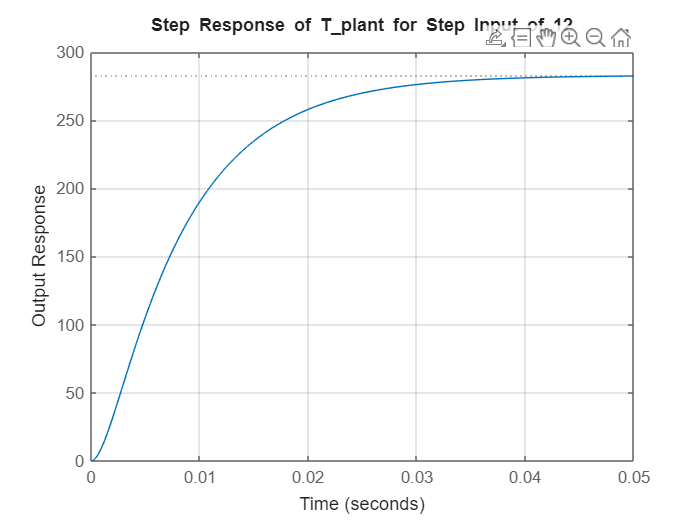

% Plot step response for T_plant
figure;
step(280*12*T_plant);
xlabel('Time');
ylabel('Output Response');
title('Step Response of T\_plant for Step Input of 12');
grid on;

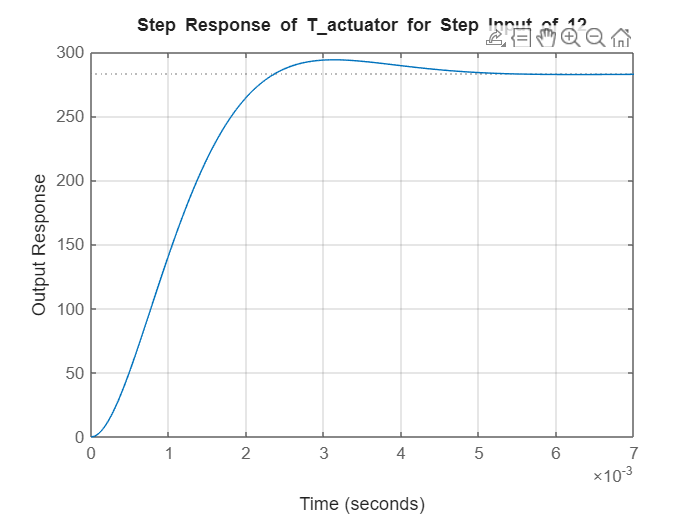


% Plot step response for T_actuator
figure;
step(280*12*T_actuator);
xlabel('Time');
ylabel('Output Response');
title('Step Response of T\_actuator for Step Input of 12');
grid on;